% Add functions in `conv-xy` to MATLAB path.
addpath('conv-xy/functions');

% Load One File
[File, Path] = uigetfile('*.dat');
fprintf("Reading %s ... ", File);

Reading chair.dat ... 

dat = read_bf_file(strcat(Path, File));
empty_cells = cellfun('isempty', dat);
dat(empty_cells) = [];
if ~isempty(dat)
  fprintf('OK! (%d pkts, %d x %d MIMO)\n', length(dat), dat{1}.Ntx, dat{1}.Nrx);
else
  fprintf('No Packet!!\n');
end

OK! (282821 pkts, 1 x 3 MIMO)


raw = process_dat( ...
    File, Path, 2000, [1], [1], true, true, '', ...
    false, true, dat, ...
    false, 0, 0, ...
    false, 0, 0 );

Starts to convert a DAT file!
[1] Reading data ... OK! (282821 pkts, 1 x 3 MIMO)
[2] Calculating Tx/Rx count... OK!
[3] Initializing data space... OK!
[4] Scaling into linear... OK! (56.163460 seconds)
[5] Consider uniqueness... OK!
[6] Select Tx/Rx pairs... OK!
[7] Permuting amplitude... OK!
[8] Reshaping & filtering amplitude... OK!
[9] Permuting phase... OK!
[10] Calibrating & filtering phase... OK!
[11] Merging into windows... OK!
[12] Final: Concatenating timestamp and csi... OK!
Successfully converted to CSV.


rawts = raw(:, 1);
rawsamp = raw(:, 11);
rawsphase = raw(:, 46);
rawmamp = mean(raw(:, 2:31), 2);
rawmphase = mean(raw(:, 32:61), 2);

% Configuration
pps = 100;

tx = [1];
rx = [1, 2, 3];

amp = true;
phase = true;

use_hampel = true;
hampel_k = floor(pps * 0.09);
hampel_sigma = 3;

use_sgolay = true;
sgolay_order = 3 + floor(pps / 300);
sgolay_frame_amp = floor(pps * 0.09);
sgolay_frame_phase = floor(pps * 0.11);

% Process one file (full)
trx = length(tx) * length(rx);
if (mod(sgolay_frame_amp, 2) == 0)
    sgolay_frame_amp = sgolay_frame_amp + 1;
end
if (mod(sgolay_frame_phase, 2) == 0)
    sgolay_frame_phase = sgolay_frame_phase + 1;
end
filt = process_dat( ...
    File, Path, pps, tx, rx, amp, phase, '', ...
    false, true, dat, ...
    use_hampel, hampel_k, hampel_sigma, ...
    use_sgolay, sgolay_order, sgolay_frame_amp, sgolay_frame_phase );

Starts to convert a DAT file!
[1] Reading data ... OK! (282821 pkts, 1 x 3 MIMO)
[2] Calculating Tx/Rx count... OK!
[3] Initializing data space... OK!
[4] Scaling into linear... OK! (56.163460 seconds)
[5] Consider uniqueness... OK!
[6] Select Tx/Rx pairs... OK!
[7] Permuting amplitude... OK!
[8] Reshaping & filtering amplitude... OK!
[9] Permuting phase... OK!
[10] Calibrating & filtering phase... OK!
[11] Merging into windows... OK!
[12] Final: Concatenating timestamp and csi... OK!
Successfully converted to CSV.


ts = filt(:, 1);
samp = filt(:, 11);
sphase = filt(:, 30 * trx + 46 + 1);
mamp = mean(filt(:, 2:31), 2);
mphase = mean(filt(:, (2 + 30 * trx):(1 + 30*(1 + trx))), 2);

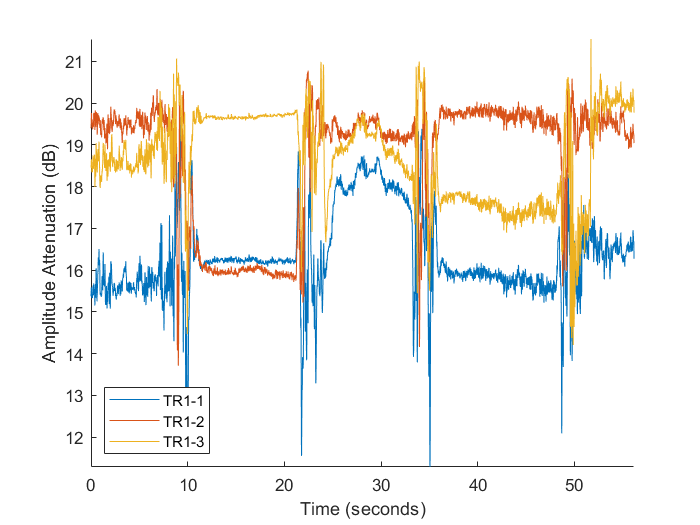

% Look all packets
if (amp)
    f3 = figure(3);
    clf(f3);
    hold on;
    legis = cell(1, trx);
    for p = 1:trx
        plot(filt(:, 1), mean(filt(:, (2 + 30*(p - 1)):(1 + 30*p)), 2));
        legis{p} = ['TR' num2str( ...
            1 + floor(p / (length(rx) + 1))) '-' num2str( ...
            mod(p, length(rx) + 1))];
    end
    hold off;
    legend(legis, 'Location', 'southwest');
    xlabel("Time (seconds)");
    ylabel("Amplitude Attenuation (dB)");
    axis([0 ts(length(ts)) -inf inf]);
end

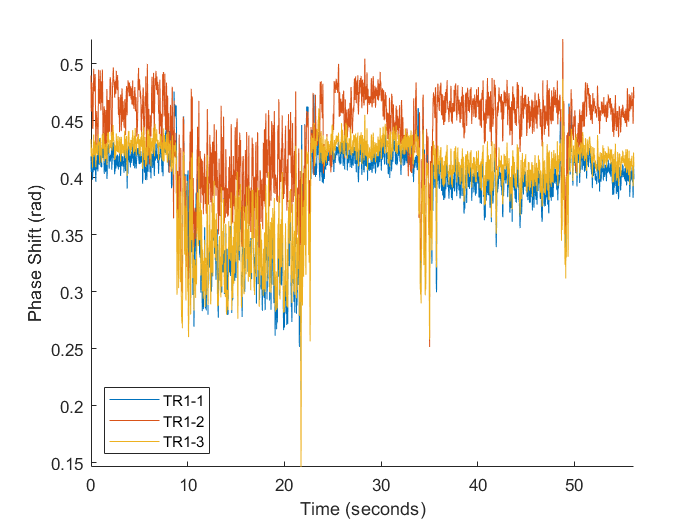

if (phase)
    f4 = figure(4);
    clf(f4);
    hold on;
    legis = cell(1, trx);
    for p = 1:trx
        plot(filt(:, 1), mean(filt(:, ...
            (2 + 30*(p - 1 + trx)):(1 + 30*(p + trx))), 2));
        legis{p} = ['TR' num2str( ...
            1 + floor(p / (length(rx) + 1))) '-' num2str( ...
            mod(p, length(rx) + 1))];
    end
    hold off;
    legend(legis, 'Location', 'southwest');
    xlabel("Time (seconds)");
    ylabel("Phase Shift (rad)");
    axis([0 ts(length(ts)) -inf inf]);
end

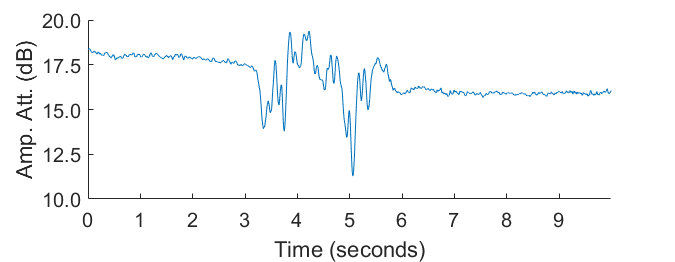

% Cut data and select tx/rx!
stx = [1];
srx = [1];
sstart = 30;
send = sstart + 10;
sadd_legend = false;
sadd_label = true;

% Draw really you want!
scsi = filt((floor(pps * sstart + 1)):(floor(pps * send)), :);
sts = ts(1:length(scsi));

if (amp)
    f1 = figure(1);
    set(f1, 'Position', [0 0 540 210]);
    clf(f1);
    hold on;
    legis = cell(1, length(srx) * length(stx));
    for t = 1:length(stx)
        for r = 1:length(srx)
            p = (t - 1) * length(srx) + r;
            plot(sts, mean(scsi(:, (2 + 30*(p - 1)):(1 + 30*p)), 2));
            legis{p} = ['TR' num2str(t) '-' num2str(r) ];
        end
    end
    hold off;
    set(gca, 'FontSize', 12);
    set(gca, 'XTick', (0:1:10));
    set(gca, 'YTick', (10:2.5:20));
    if (sadd_legend)
        legend(legis, 'Location', 'southwest');
    end
    if (sadd_label)
        xlabel("Time (seconds)");
        ylabel("Amp. Att. (dB)");
    end
    axis([0 sts(length(sts)) 10 20]);
    ytickformat('%2.1f');
end

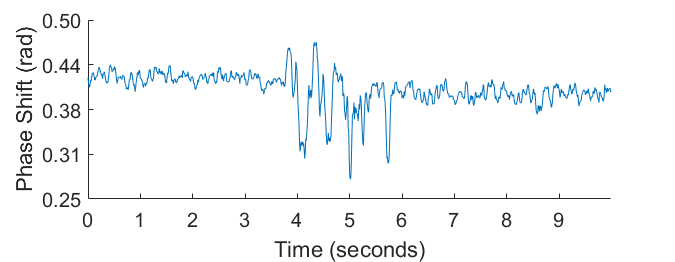

if (phase)
    f2 = figure(2);
    set(f2, 'Position', [0 0 540 210]);
    clf(f2);
    hold on;
    legis = cell(1, length(srx) * length(stx));
    for t = 1:length(stx)
        for r = 1:length(srx)
            p = (t - 1) * length(srx) + r;
            plot(sts, mean(scsi(:, ...
                (2 + 30*(p - 1 + trx)):(1 + 30*(p + trx))), 2));
            legis{p} = ['TR' num2str(t) '-' num2str(r) ];
        end
    end
    hold off;
    set(gca, 'FontSize', 12);
    set(gca, 'XTick', (0:1:10));
    set(gca, 'YTick', (0.25:0.0625:0.5));
    if (sadd_legend)
        legend(legis, 'Location', 'southwest');
    end
    if (sadd_label)
        xlabel("Time (seconds)");
        ylabel("Phase Shift (rad)");
    end
    axis([0 sts(length(sts)) 0.25 0.5]);
    ytickformat('%1.2f');
end

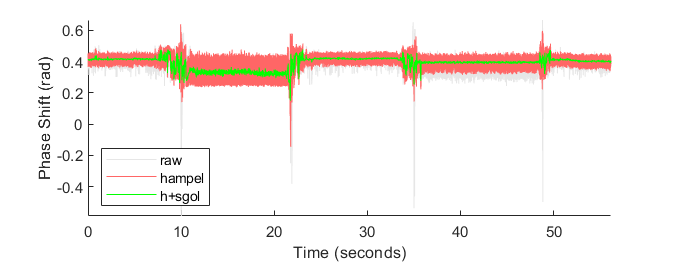

% Check filters on phase

cphasehampx = 0.09;
cphasesgolx = 0.11;

% cphaseori = rawsphase; cphasets = rawts; cphasepps = 2000;
cphaseori = rawmphase; cphasets = rawts; cphasepps = 2000;
% cphaseori = sphase; cphasets = ts; cphasepps = pps;
% cphaseori = mphase; cphasets = ts; cphasepps = pps;

%% AUTOMATIC PART BELOW %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

if (mod(floor(cphasepps * cphasesgolx), 2) == 0)
    cphasesglenaddi = 1;
else
    cphasesglenaddi = 0;
end

cphasehamp = hampel(cphaseori, floor(cphasepps * cphasehampx), 3);
cphasesgol = sgolayfilt(cphasehamp, ...
    3 + floor(cphasepps / 300), floor(cphasepps * cphasesgolx) + cphasesglenaddi);

clf;
hold on;
plot(cphasets, cphaseori, 'color', [0, 0, 0]+0.9);
plot(cphasets, cphasehamp, 'color', [1.0, 0.4, 0.4]);
plot(cphasets, cphasesgol, 'color', [0, 1.0, 0]);
hold off;
legend({'raw', 'hampel', 'h+sgol'}, 'Location', 'southwest');
ylabel("Phase Shift (rad)");
xlabel("Time (seconds)");
axis([0 cphasets(length(cphasets)) -inf inf]);

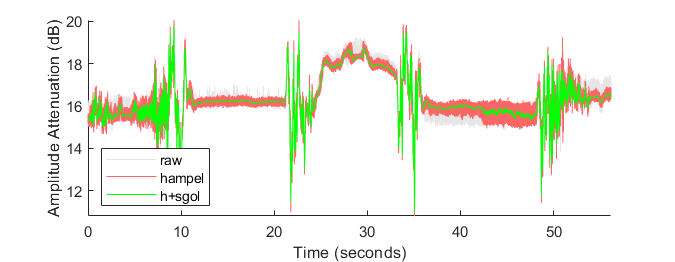

% Check filters on amplitude

camphampx = 0.09;
campsgolx = 0.11;

% campori = rawsamp; campts = rawts; camppps = 2000;
campori = rawmamp; campts = rawts; camppps = 2000;
% campori = samp; campts = ts; camppps = pps;
% campori = mamp; campts = ts; camppps = pps;

%% AUTOMATIC PART BELOW %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

if (mod(floor(camppps * campsgolx), 2) == 0)
    campsglenaddi = 1;
else
    campsglenaddi = 0;
end

camphamp = hampel(campori, floor(camppps * camphampx), 3);
campsgol = sgolayfilt(camphamp, ...
    3 + floor(camppps / 300), floor(camppps * campsgolx) + campsglenaddi);

clf;
hold on;
plot(campts, campori, 'color', [0, 0, 0]+0.9);
plot(campts, camphamp, 'color', [1.0, 0.4, 0.4]);
plot(campts, campsgol, 'color', [0, 1.0, 0]);
hold off;
legend({'raw', 'hampel', 'h+sgol'}, 'Location', 'southwest');
ylabel("Amplitude Attenuation (dB)");
xlabel("Time (seconds)");
axis([0 campts(length(campts)) -inf inf]);